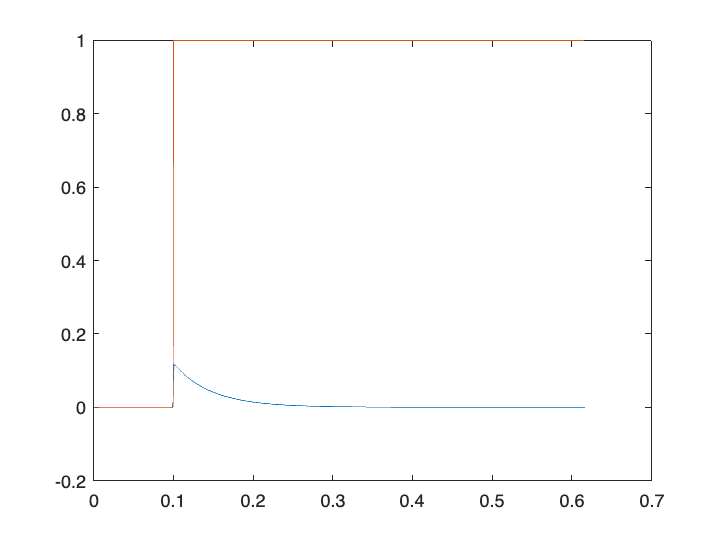

clear all;

% Parámetros de simulación

T = 0.65;  % Tiempo total de simulación
N = 512*2; % Número de puntos de muestreo
error = 0.0001;
dw = pi/T;  % Paso en frecuencia
dt = T/N;  % Paso de tiempo

% Criterio para determinar el coeficiente de amortiguamiento c
% c = 2*dw;  % Opción 1

c = log(N^2)/T;  % Opción 2 (utilizada en el código)

% Vectores de tiempo y frecuencia

t = dt*(0:N-1);
n = 0:N-1;
m = 1:2:2*N;
s = c + 1i*m*dw;
Cn = (N*2*dw/pi)*exp(c*dt+1i*n*pi/N);

% Función en el dominio s

tau = 0.1;
Fs = (1./s).*exp(-tau*s);

% Selección de la ventana (descomentar la que se desee)
% sigma = 0.5*(1+cos(0.5*pi*m/N));  % Hanning
% sigma = sin(0.5*pi*m/N)./(0.5*pi*m/N);  % Lanczos

sigma = 0.42+0.5*cos(0.5*pi*m/N)+0.08*cos(pi*m/N);  % Blackman

% Aplicación de la ventana

Fs = Fs.*sigma;

% Transformada inversa de Fourier

ftd = ifft(Fs);
ftd = real(Cn.*ftd);

% Función en el dominio del tiempo (analítica)

x = find(t >= tau);
ft = [zeros(1,x(1)-1) ones(1,N-x(1)-1)];

% Graficar resultados

Np = floor(N*0.95);
figure;
plot(t(1:Np),real(ftd(1:Np)),t(1:Np),ft(1:Np));

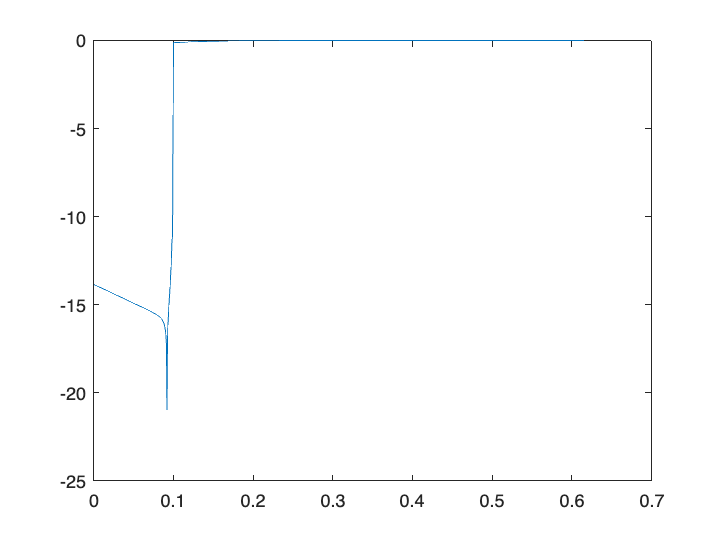

figure;
plot(t(1:Np),log(abs(real(ftd(1:Np))-ft(1:Np))));


function y = DNLT(ftd, c, dt)
% DNLT: Calcula la transformada de Laplace discreta de una señal.

% Entrada:
%   ftd: Vector de valores de la señal en el dominio del tiempo.
%   c: Factor de amortiguamiento.
%   dt: Paso de tiempo.

% Salida:
%   y: Transformada de Laplace discreta de la señal.

% Obtener la longitud de la señal

order = size(ftd);
N = order(2);

% Crear un vector de índices

n = 0:N-1;

% Calcular la exponencial compleja

exp1 = exp(-c*dt - 1i*pi/N).^n;

% Multiplicar la señal por la exponencial

fw = ftd .* exp1;

% Aplicar la transformada de Fourier discreta

y = dt * fft(fw);
end